# Segmentation of Images

In this script, I am trying to show how various segmentation methods can be employed to extract the **relevant** features from an image. The script is divided into the following sections -

- Spatial filtering (as pre-segmentation process)

- Thresholding based segmentation

- Edge-detection based segmentation

### Building the code from previous scripts

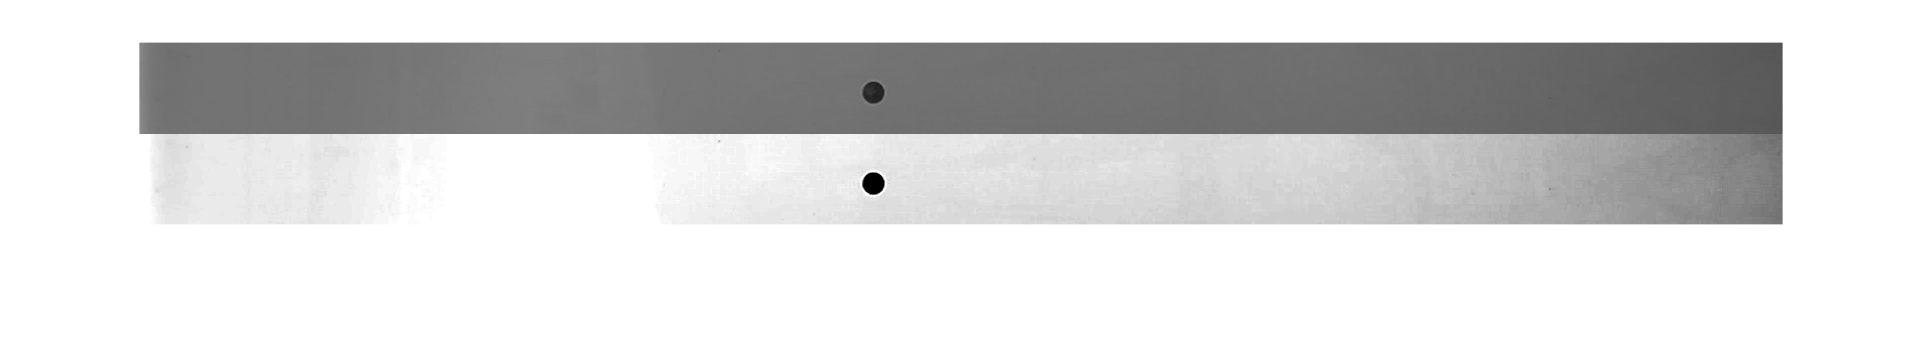

% Reading an image
img=imread("../../data/data_sedimentation/sphere.png");  % image of a sphere

% converting to grayscale
img_gray=im2gray(img);

% cropping the image
crop_rect=[288.5 490.5 1629 89];
img_crop=imcrop(img_gray,crop_rect);

% adjusting the contrast
img_adj=imadjust(img_crop,[60/255,120/255],[0/255,255/255]);

% Visualising
figure;
montage({img_crop,img_adj})

## Part 1 - Spatial filtering

In this step, our goal will be to apply some artificial smoothening so that the main features of the images becomes stronger compared to any noise present in it. It is a unspoken rule that applying some smoothening or filtering gives better segmentation results.

There are multiple ways to do the filtering. The mathematics and the detail of these can be found [here](https://uk.mathworks.com/help/images/linear-filtering.html).

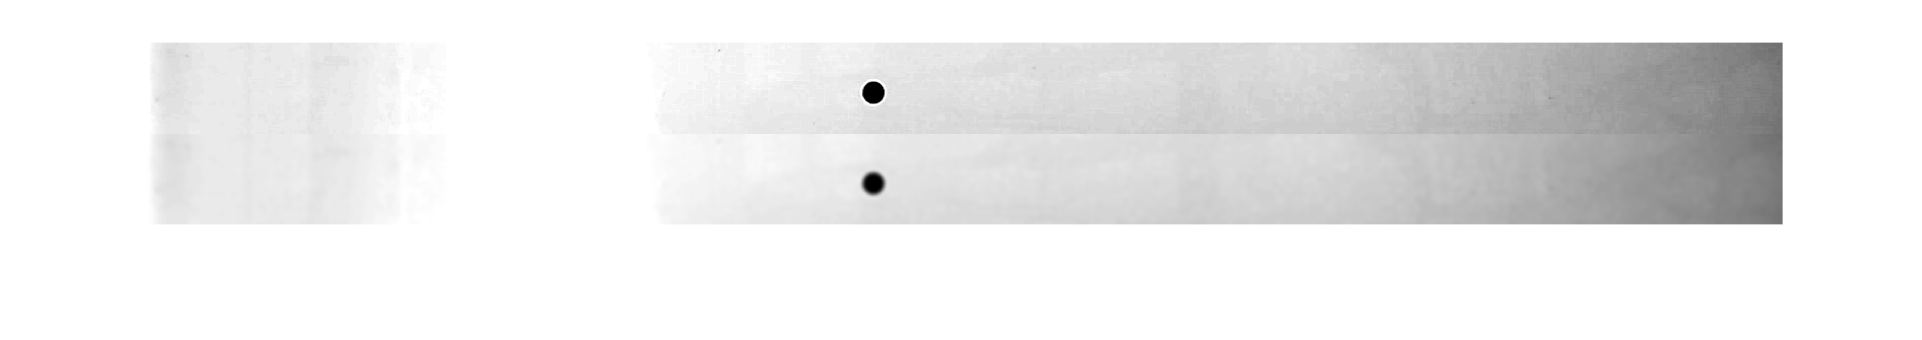

gaussian_filter=2;   % strength of filtering
img_filter=imgaussfilt(img_adj,gaussian_filter);

figure;
montage({img_adj,img_filter})

## Part 2 - Thresholding

Thresholding is a process by which we can separate an image into a foreground (the region of importance to us from an extraction of features point of view) and background (region which is not of importance to us from feature extraction point of view). Therefore, we can carefully select a pixel level that will signify that boundary between the foreground and the background.

There are multiple ways of doing this thresholding. In MATLAB we use **imbinarize** function for this purposes.

### Method - 1: Global Thresholding

This is based on Otsu's algorithm. If you are interested to know more about the algorithm, follow MATLAB's official documentation [here](https://uk.mathworks.com/help/images/ref/imbinarize.html#bu1w0rc-1-method).

img_bw_global=imbinarize(img_filter,"global");

### Method - 2 : Adaptive Thresholding

img_bw_adap=imbinarize(img_filter,"adaptive");

### Comparison of Method 1 & Method 2

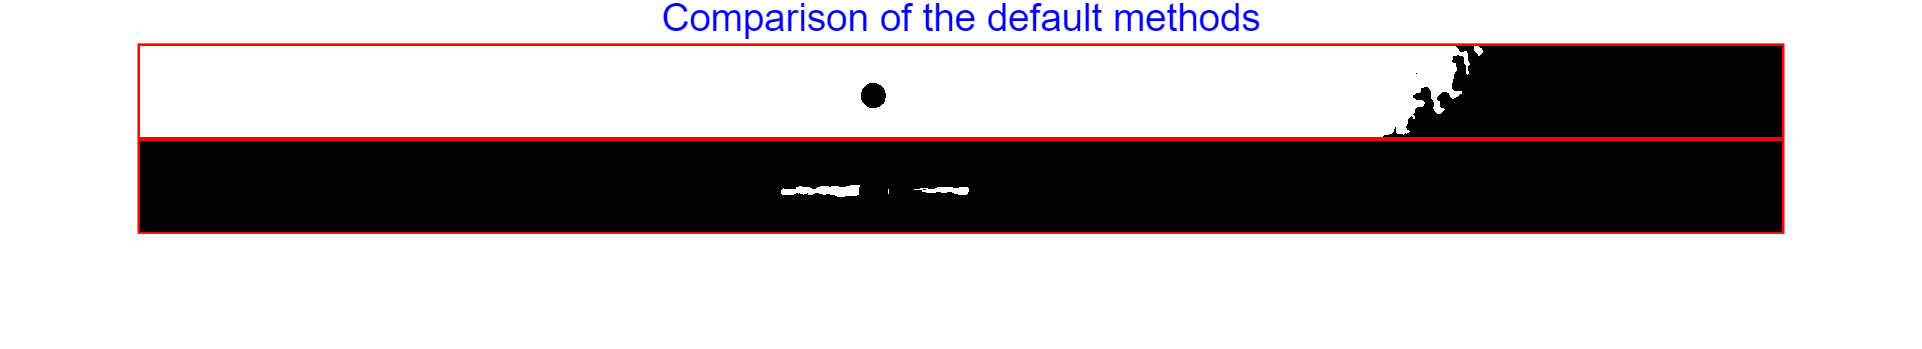

figure;
montage({img_bw_global, img_bw_adap}, ...
    'BorderSize', [10 10], ...
    'BackgroundColor', 'r');
title("Comparison of the default methods",fontsize=14,fontweight='normal',color='b')

The global thresholding gives the sphere. However, the adaptive thresholding is not at all effective.

### Method - 3: Choosing on our own

The approach is to inspect the histogram of the image and try to select a pixel level which can classify the image into a foreground and a background.

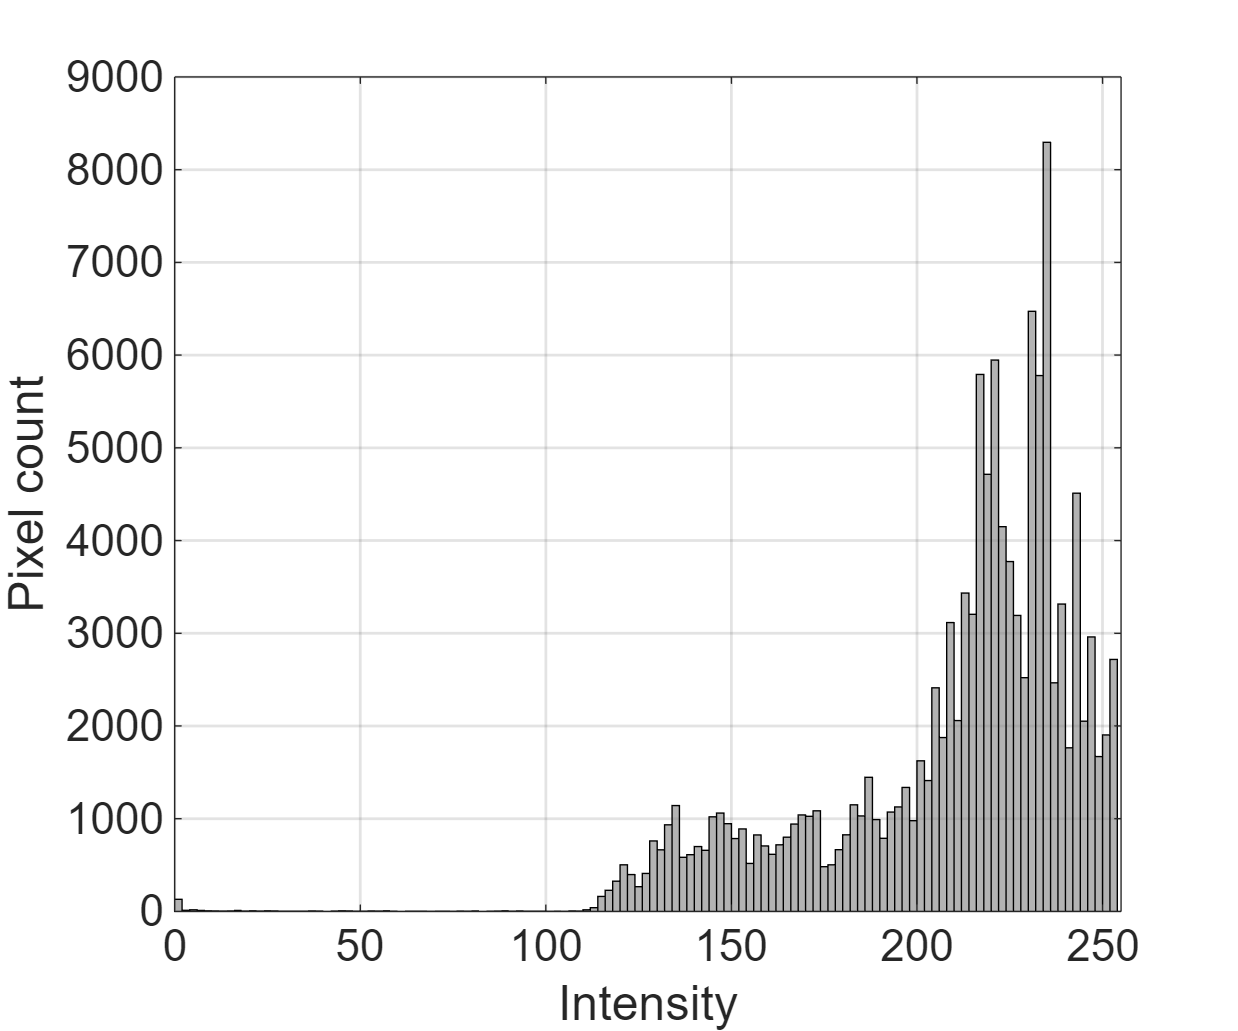

VisualiseHistogram(img_filter,2);

Looking into the figure above, most of the pixels are beyound 100 pixel levels. Also be mindful that you are trying to extract a very tiny object or foreground from a very large background. Hence pixel levels as well as pixel counts are important to keep in mind.

*Note* : Following are some of the points that you should keep in mind

- Mind you, this is an approach and not a prescription. What values will be give the best outcome will come naturally with looking more into the images.

- Keep in mind that you are taking a thresholing value from a single frame. Your success also the processing will also depend whether the same factor holds for all other images from your particular experiment.

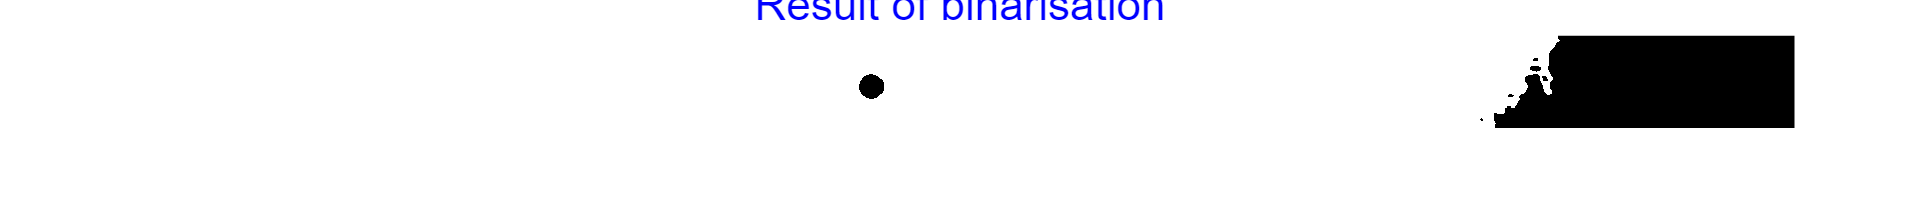

img_bw_manual=imbinarize(img_filter,180/255);
image_viewer(img_bw_manual,'Result of binarisation')

### Understanding the effect of binarisation on the sphere

data_sphere=regionprops(~img_bw_manual,'Area');
fprintf("Area of the sphere (in pixels) = %d\n",data_sphere(1).Area)

Area of the sphere (in pixels) = 463


Depending upon the thresholding, the area of your sphere might be different. Therefore, you need to careful while extracting meanings out of the image processing operation.

## Part 3 - Edge detection

- Another most widely used method of extracting features from an image is to find an edge from the image. An edge is defined as a line of width =1 pixel. 

- We will use the function [edge](https://uk.mathworks.com/help/images/ref/edge.html) to find out the edge of an image.

- There are several different methods or algorithms to find an edge. The one that I have used regularly is known as the *Canny* algorithm.

### Applying Canny algorithm

For correctly applying the **Canny** method, following are the things to keep in mind -

- The algorithm requires you to provide gaussian filtering to the image by default. I normally apply prior to the default method and that works well from experience.

- The algorithm requires two threshold values. Mind you, these threshold values are different from the one encountered while using the *imbinarize* function. The choice of these threshold values are not very intuitive (to me).

- There are definitely mathematical meaning of these values which require you to study the algorithm.

- However, from a practically standpoint, you can assume the first value to be a lower threshold of the smallest details you want to detect within the image. The other value is the higher threshold, denoting (practically) the largest details required for detection.

However, the selecting the lower & higher threshold is not prescriptive and the suitable choice comes from applying the image again and again in images.

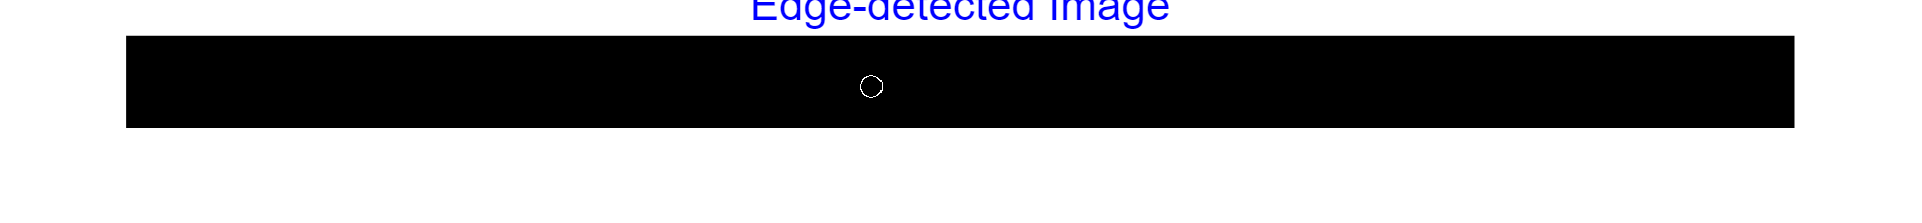

% Canny algorithm parameters
canny_sigma=1;   % for in-built filtering in the method
canny_threshold_rect=[0.001,0.1];

% applying canny
img_canny=edge(img_filter,'canny',canny_threshold_rect,canny_sigma);
image_viewer(img_canny,"Edge-detected Image")

### Post processing - how circular is the edge?

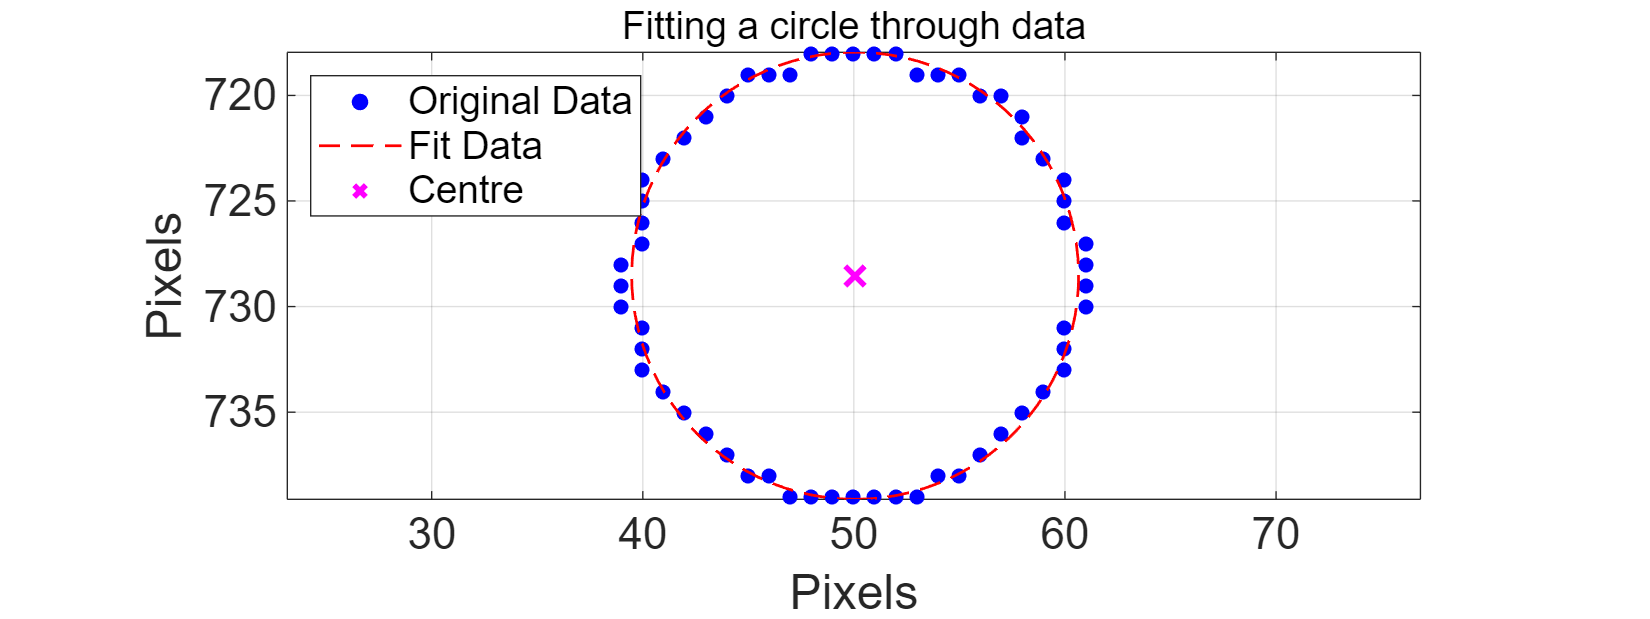

% Post analysis - to see how circular is the detected sphere
[bw_rows,bw_cols]=find(img_canny);
data=[bw_cols,bw_rows];   % Nx2 arrat

% fitting a circle
d=curvature_measurement_function(data,img_canny,true,false);